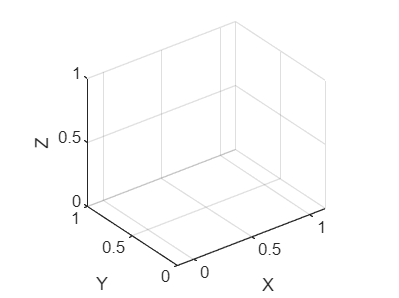

% --- 1. ล้างค่าเก่าทั้งหมดก่อน (สำคัญมาก เพื่อแก้ Error) ---
clear; clc; close all;

% --- 2. อ่านไฟล์ CSV ---
filename = 'Waypoints_with_z4point.csv'; % ชื่อไฟล์ของคุณ
if exist(filename, 'file') ~= 2
    error('หาไฟล์ไม่เจอครับ ตรวจสอบชื่อไฟล์อีกที');
end

data = readtable(filename);

% แปลงข้อมูลให้เป็น double (ตัวเลข) เผื่อ MATLAB อ่านมาเป็นอย่างอื่น
x = double(data.x);
y = double(data.y);
z = double(data.z);

% --- 3. ตั้งค่า Figure และระบุ Axes ให้ชัดเจน ---
f = figure('Color', 'w');
ax = gca; % (Get Current Axes) ดึงค่าแกนปัจจุบันมาเก็บไว้
grid(ax, 'on');
axis(ax, 'equal');
view(ax, 3);
xlabel(ax, 'X'); ylabel(ax, 'Y'); zlabel(ax, 'Z');

% สร้าง animatedline โดยระบุ parent เป็น ax (แก้ปัญหา Handle หลุด)
hLine = animatedline(ax, 'Color', 'b', 'LineWidth', 1.5);

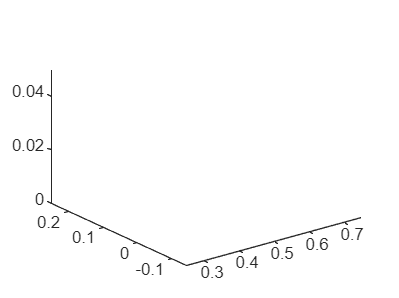

hHead = plot3(ax, nan, nan, nan, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 6);

% ตั้งขอบเขต (Optional: ช่วยให้กราฟไม่กระตุกตอนขยาย)
if ~isempty(x)
    xlim([min(x) max(x)]);
    ylim([min(y) max(y)]);
    zlim([min(z) max(z)]);
end


disp('Start Drawing...');

Start Drawing...



% --- 4. Animation Loop ---
for i = 1:length(x)
    % ตรวจสอบว่าหน้าต่างกราฟยังเปิดอยู่ไหม (กัน Error เวลาปิดหน้าต่างกลางคัน)
    if ~isvalid(hLine) 
        break; 
    end
    
    % เพิ่มจุด (ใช้ hLine ที่ผูกกับ ax แล้ว)
    addpoints(hLine, x(i), y(i), z(i));
    
    % ขยับหัวปากกา
    set(hHead, 'XData', x(i), 'YData', y(i), 'ZData', z(i));
    
    % วาดทันที
    drawnow limitrate; 
end

disp('Finished.');

Finished.
